# DC Motor Control Lab 1: Modeling and Analysis

## Part I: Transfer function model

In this part of the lab, you will derive the transfer function model of the DC motor and then simulate its response in MATLAB and Simulink. You will also analyze the stability of the transfer function model by examining its poles.

#### **Derivation of the DC motor differential equations**

A DC motor works by conducting a current through an armature that can rotate freely. The fixed brushes transmit the current to the rotating commutators. The current flowing through the armature passes through a magnetic field generated by the stator magnets, resulting in a Lorentz force in the perpendicular direction ($\mathbf{F} = i\mathbf{\ell} \times \mathbf{B}$, where $\mathbf{\ell}$ points in the wire direction). The two sides of the armature each produce a force, resulting in a net torque on the rotor $T$. If sufficient torque is applied, the shaft rotates, changing the angular position $\theta$.

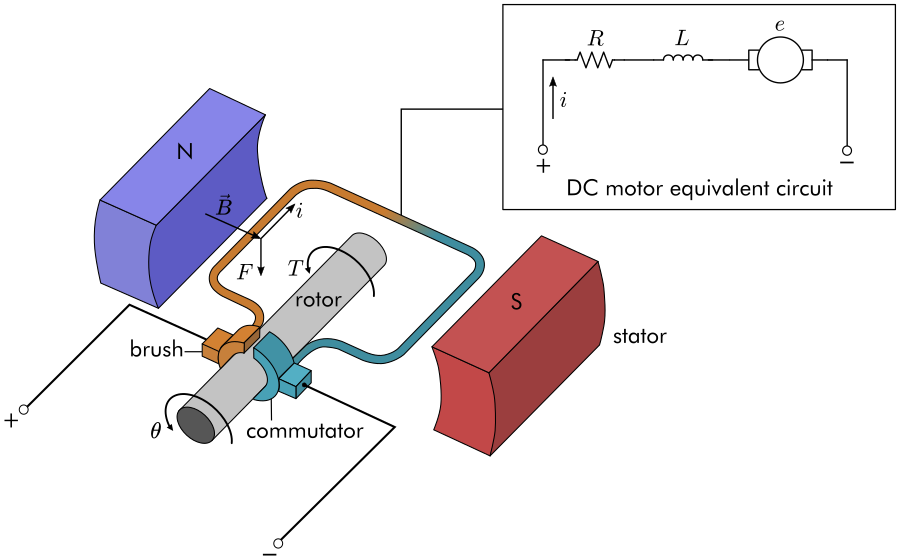

*DC motor schematic. A net torque *$T$ *is generated on the armature by Lorentz forces. In the electrical domain, the motor is represented by a series of three circuit elements.*

**Derivation of the DC motor differential equations**

Under typical operating conditions, the torque generated by a DC motor is directly proportional to the current passing through it:


$$T = k_mi$$


where $k_m$ is a proportionality constant determined by the characteristics of the specific motor. This relationship fails for large values of $i$. 

When the armature rotates, it generates a back electromotive force ([back EMF](https://en.wikipedia.org/wiki/Counter-electromotive_force)) that opposes the applied voltage. In the circuit diagram, this is represented by a motor symbol. The voltage drop due to the back EMF, denoted $e$, is proportional to the rotational velocity of the armature:


$$e =k_e \dot{\theta}$$


where $k_e$ is a constant of proportionality. To derive the relationship between the current $i$ and the motor shaft angular position $\theta$, you can apply Kirchhoff's voltage law and Newton's second law in terms of torques acting on the motor shaft. Kirchhoff's voltage law implies that the sum of the voltage drops across the circuit must equal the applied voltage:


$$iR + L \frac{di}{dt} + k_e \dot{\theta} = v$$
    
$$(1)$$


where $v$ is the electric potential applied to the motor. In the absence of other applied torques, the equation of motion can be derived by balancing the inertia of the motor shaft ($J \ddot{\theta}$) with the applied torque ($T$) and frictional resistance ($B \dot{\theta}$).


$$J \ddot{\theta}  = T - B \dot{\theta}$$


Using the linear relationship between torque and current, this is equivalent to:


$$J \ddot{\theta} + B \dot{\theta}  = k_m i$$
    
$$(2)$$
   

#### Transfer function model

 **Task 1**. Follow the steps below to derive the angular velocity transfer function model of the DC motor equations. Assume that the system starts at rest ($i = i' = \theta = \dot{\theta} = 0$). 

- Compute the Laplace transform of the voltage conservation equation (1) and apply the initial conditions. 

- Compute the Laplace transform of the equation of motion (2) and apply the initial conditions. 

- Use the results of the previous two steps to solve for the angular velocity transfer function $G(s) = \frac{\Omega(s)}{V(s)}$ where $\Omega$ is the Laplace transform of the angular velocity $\omega(t) = \dot{\theta}(t)$ and $V$ is the Laplace transform of the voltage: $v(t)$.

**Answer:**


$$G(s) =  \frac{k_m}{LJs^2 + (RJ+LB)s + BR + k_mk_e}$$


 **Task 2**. Define the angular velocity transfer function `G` in MATLAB using the [`tf`](https://www.mathworks.com/help/control/ref/tf.html) function using the values of the constants defined below.

- $k_m = k_e = 0.01$ V/(rad/s)

- $B = 10^{-5}$ N$\cdot$m/(rad/s)

- 
$$R = 8 \ \Omega$$


- $L = 5 \cdot 10^{-6}$ H

- $J = 2 \cdot 10^{-6}$ kg$\cdot$m$^2$

  **Pro-tip**: To define a transfer function in MATLAB, use `tf` with the syntax `tf(num,den)` where `num `and `den` represent the coefficients of the numerator and denominator in descending order. For example, $H = 2s/(s^2 + 2)$ is defined in MATLAB as

% Answer
km = 0.01;
ke = 0.01;
B = 1e-5;
R = 8;
L = 5e-6;
J = 2e-6;

G = tf([0 0 km],[L*J, R*J+L*B, B*R+km*ke])

G =
 
               0.01
  -------------------------------
  1e-11 s^2 + 1.6e-05 s + 0.00018
 
Continuous-time transfer function.



 **Task 3**. Compute the step response of the transfer function using the [`step`](https://www.mathworks.com/help/control/ref/lti.step.html) function. Multiply the transfer function by 6 to represent an input step voltage of 6V.

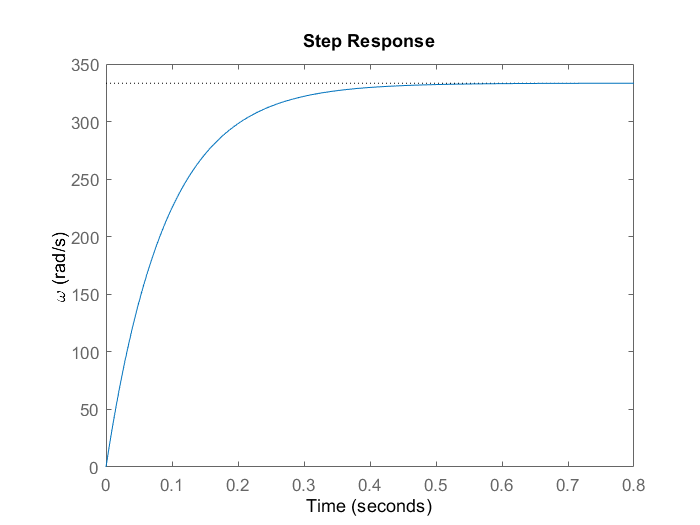

step(6*G)
ylabel("\omega (rad/s)")

The correct response is shown below for reference.

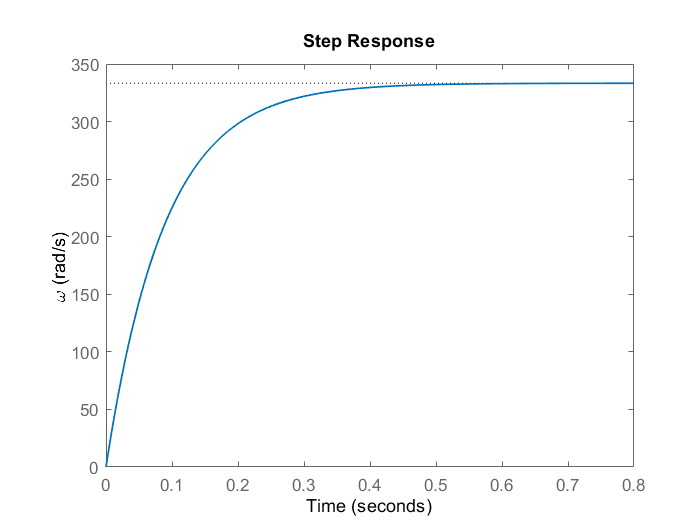

*Step response of *$6G$

 **Task 4. **Create a [Simulink model](matlab: open_system(new_system);) that computes the step response of the same transfer function. 

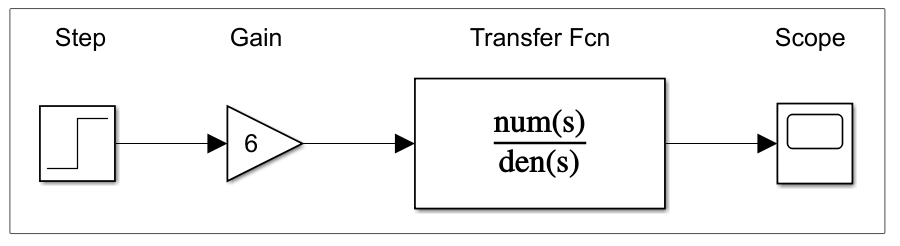

*Simulink model that computes the DC motor's response to a 6V step input*

Use the following blocks and connect them as shown in the model diagram.

- A [Step](https://www.mathworks.com/help/simulink/slref/step.html) block with Step time: 0, Initial value: 0, Final value: 1, Sample time: 0.

- A [Gain](https://www.mathworks.com/help/simulink/slref/gain.html) block with Gain: 6 (so that the input voltage is 6V).

- A [Transfer Fcn](https://www.mathworks.com/help/simulink/slref/transferfcn.html) block with the numerator and denominator set to match the MATLAB transfer function you defined above.

- A [Scope](https://www.mathworks.com/help/simulink/slref/scope.html) block so that you can observe the velocity $\omega$.

 **Pro-tip**: Double-click anywhere on the Simulink canvas and type the name of the block you want to add.

 **Task 5. **Set the simulation Stop Time to 0.8s. Run the model and double-click the scope. If correct, your Simulink model scope plot should match the output computed in MATLAB.

 **Task 6. **Answer the following questions. Use your Simulink model and make adjustments as necessary.

- What is the maximum speed of motor under these loading conditions in RPM? Note that $\omega = \dot \theta$ has units of rad/s. **Answer: 3182 rpm**

- Suppose that the input voltage is increased to 12 V. Will the maximum speed of the motor increase, decrease, or stay the same? **Answer: increase.**

- Verify your answer by changing the gain value in the Simulink model. What is the maximum speed in RPMs? **Answer: 5674 rpm.**

- Suppose that the inertia of the motor shaft is increased to $J = 5 \cdot 10^{-6}$ kg$\cdot$m$^2$. Will the maximum speed of the motor increase, decrease, or stay the same? **Answer: stay the same.**

- Verify your answer to (2) by changing the value of $J$ and recomputing the step response. If the maximum speed changed, what is the new maximum speed? If it didn't change, what did change, and by how much? **Answer: the rise time is doubled.**

#### Model stability

Recall that the poles of a transfer function determine its general behavior and stability.

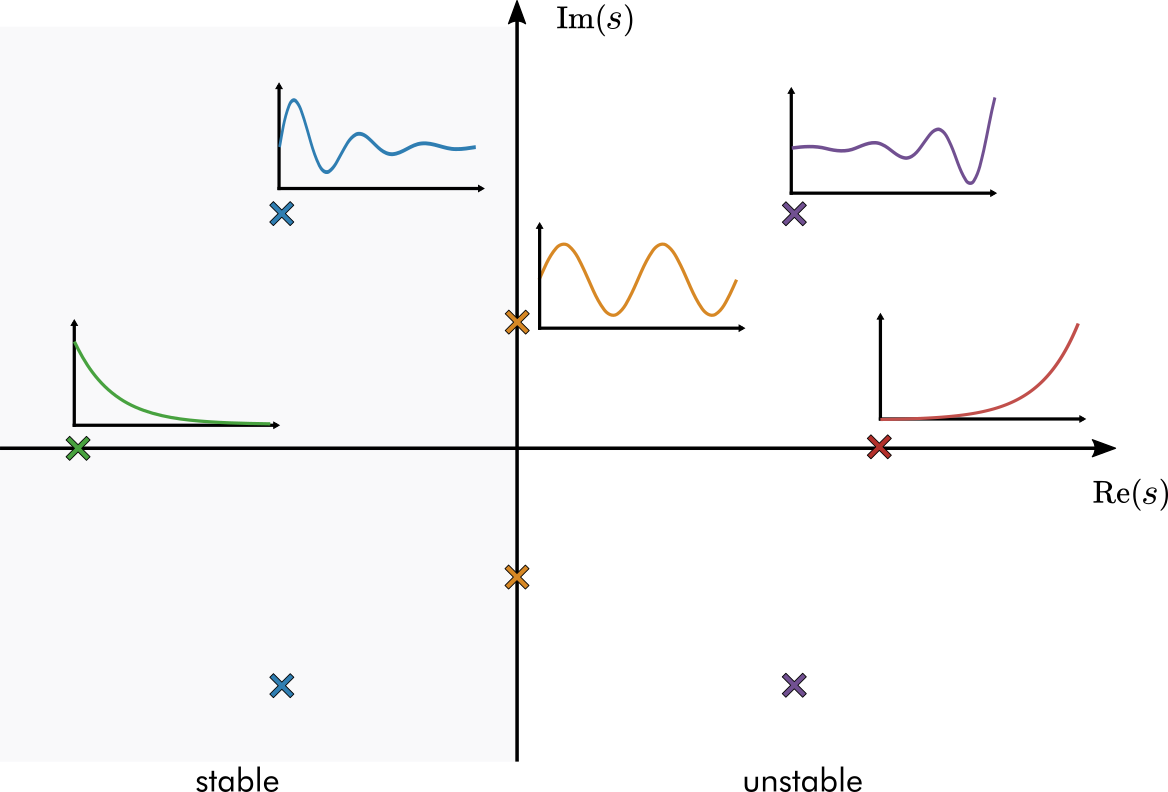

* Impulse responses characterized by the position of poles in the complex *$s$*-plane. Poles in the left-half plane (where *$\text{Re}(p) < 0$*) are stable.*

In this section, you will compute the stability of the DC motor transfer function.

 **Task 7**. Define the DC motor angular velocity transfer function `G` in MATLAB using the [`tf`](https://www.mathworks.com/help/control/ref/tf.html) function using the values of the constants defined below. 

- $k_m = k_e = 0.01$ V/(rad/s)

- $B = 10^{-5}$ N$\cdot$m/(rad/s)

- 
$$R = 8 \ \Omega$$


- $L = 5 \cdot 10^{-6}$ H

- $J = 2 \cdot 10^{-6}$ kg$\cdot$m$^2$

**Hint**: reuse your code from **Task 2** but double-check the parameters.

% Answer
km = 0.01;
ke = 0.01;
B = 1e-5;
R = 8;
L = 5e-6;
J = 2e-6;

G = tf([0 0 km],[L*J, R*J+L*B, B*R+km*ke])

G =
 
               0.01
  -------------------------------
  1e-11 s^2 + 1.6e-05 s + 0.00018
 
Continuous-time transfer function.



 **Task 8**. Compute the poles of the transfer function using [`pole`](https://www.mathworks.com/help/control/ref/lti.pole.html).

pole(G)

ans = 	1.0e+06 *

  -1.599993749956054
  -0.000011250043946


Is the system stable or unstable?

 **Task 9**. $B$ is the damping term in the equations of motion ($B$ represents friction in the motor). Answer the questions below about $B$ using the code from the previous two tasks.

- Are there values of $B$ that make the system unstable? If so, give an example. **Answer: yes, B = -1.**

- Are these values physically realistic? **No.**

## Part II: Virtual DC motor

The transfer function model idealizes the DC motor. Real DC motor systems are more complicated. For example:

- The motor is loaded by additional physical components besides the motor shaft.

- A speed reducer is often used to increase the torque of the output shaft.

- The speed of the motor shaft is calculated from an encoder which introduces measurement error.

- The parameters of the motor may not be known.

In this part of the lab, you will experiment with a virtual DC motor that incorporates several of these features.

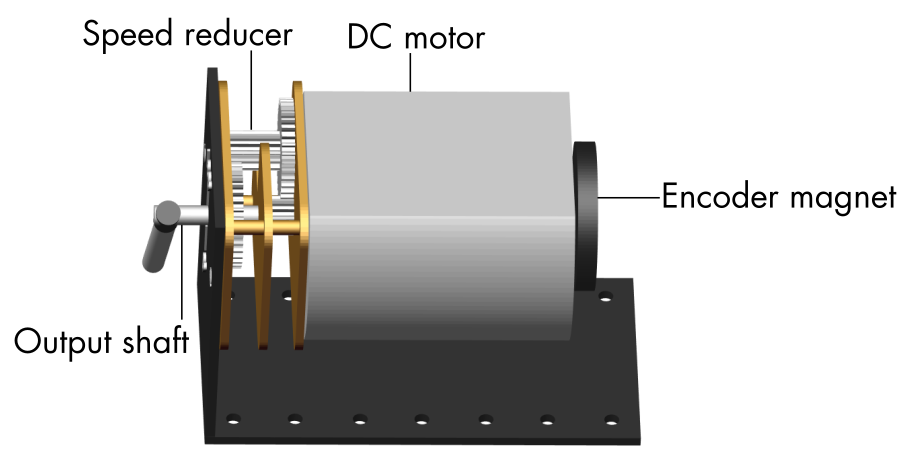

*Virtual DC motor model *

 **Task 1**. Run the virtual DC motor model.

- Open the [DC motor model](matlab: open_system("DCMotor");) (note that the model must be on the MATLAB Search Path for this link to work).

- Run the model. Notice that nothing happens because no voltage is applied to the motor.

Add the following blocks and connect them as shown in the model diagram. Then, run the model.

- A [Step](https://www.mathworks.com/help/simulink/slref/step.html) block with Step time: 1, Initial value: 0, Final value: 1, Sample time: 0.

- A [Gain](https://www.mathworks.com/help/simulink/slref/gain.html) block with Gain: 6 (so that the input voltage is 6V).

- A [Scope](https://www.mathworks.com/help/simulink/slref/scope.html) block so that you can observe the output.

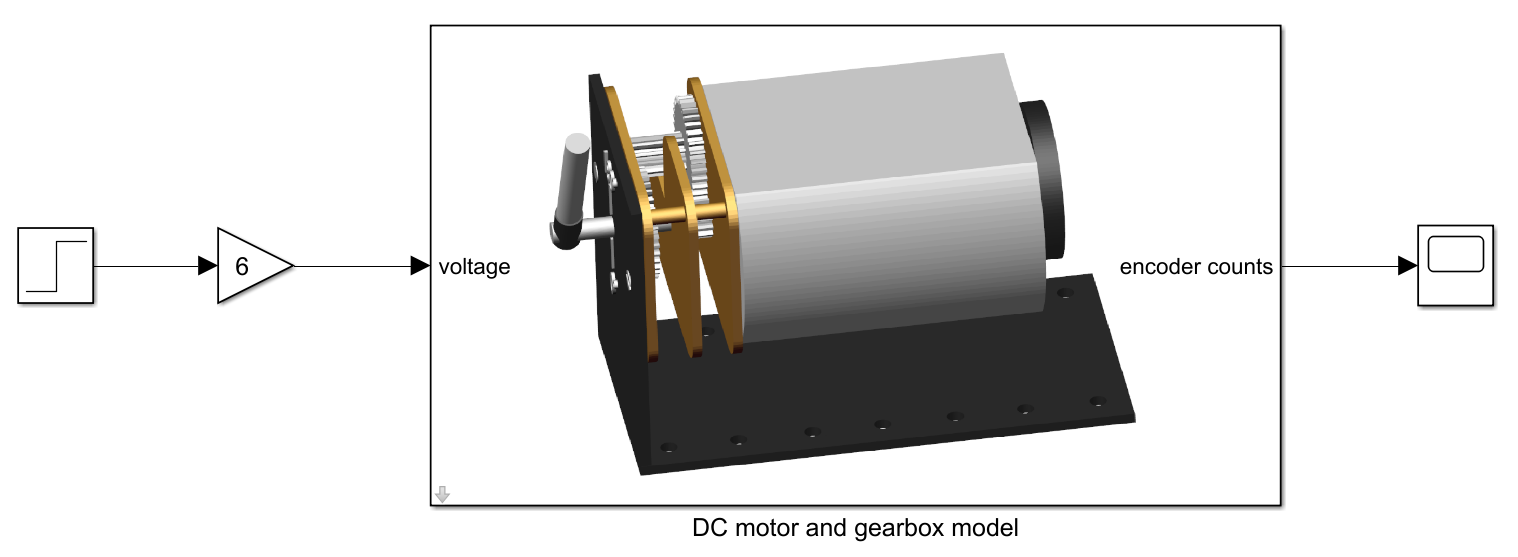

*Block diagram of the modiefied DC motor model*

- You can observe the motor running in the Mechanics Explorer. The motor runs rapidly, so it's easier to observe the response if you slow down the video speed to 1/4X or 1/8X using the slider.  

- Double click the scope block to observe the output. If correct, your output should appear as shown below.

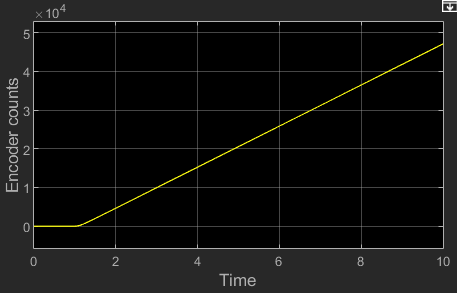

*Scope output.*

#### Measure motor shaft velocity

DC motor position and velocity can be calculated from the output of an encoder. As the motor shaft spins, the encoder generates a signal that switches between high and low logic values. Each time the signal switches, the encoder counter is iterated. The number of times that the encoder switches for each turn of the motor shaft is a known value. For the virtual model, the default is 64 counts per revolution (CPR) of the motor shaft.

 **Task 2**. Compute the position of the motor shaft from the encoder output by adding a gain block that divides the 

Task 3. Compute the velocity of the motor shaft.

Oh no, it looks terrible.

Task 4. Use a filter when computing the velocity.

Compare the transfer function response to the virtual DC motor response

Task 5. Add the transfer function to the model and connect it to the scope

Task 6. Run the model and compare the responses

Task 7. Add some weight to the pendulum. Notice how the response changes. Why does this happen? 

Output shaft 

Task 8. Compute the gear ratio.

Task 9. Use the gear ratio to compute the output shaft position and velocity.

--> In the next lab, you'll control the position and 